# Lotka-Volterra models

### Solve $\dot x = r \, x \, \left(\frac{K - x}{K}\right)$

$r$: birth rate

$K$: carrying capacity of the environment

$x(t)$: population at time $t$

syms t r K x0 real
syms x(t)

assumeAlso(K > 1)
assumeAlso(K < 10000)
assumeAlso(r > 1)
assumeAlso(r < 10)
assumeAlso(x0 > 0)


Eq = diff(x) == r*x*(K - x)/K

$$Eq(t) = \frac{\partial }{\partial t}x\left(t\right)=\frac{r\,x\left(t\right)\,\left(K-x\left(t\right)\right)}{K}$$

dsolve(Eq)

$$ans = \left(\begin{array}{c} \frac{K}{{\mathrm{e}}^{C_{1}-r\,t}+1}\\ 0\\ K \end{array}\right)$$

sol = dsolve(Eq,x(0)==x0)

$$sol = \frac{K}{{\mathrm{e}}^{\log\left(K-x_{0}\right)-\log\left(x_{0}\right)-r\,t}+1}$$

Visualize the solution

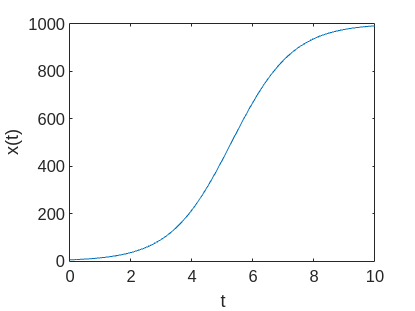

K = 1000;
r = 1;
x0 = 5;
fplot(subs(sol),[0,10]);
xlabel t
ylabel x(t)
drawnow
exportgraphics(gcf,'/home/ppolcz/Dropbox/Peti/PhD/Oktatas/11_NDS/2024/Tematika/fig/logistic.pdf','ContentType','vector')